clear all;

limits = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 12, 14, 16, 18, 20, 25, 35, 45, 60, 75, 100, 125, 150, 175, 200, 225, 250, 275, 300, 325, 350, 375, 400, 425, 450, 475, 500];

n_cells = 64;

clock_freq = 1e8;

start_index = 1;
end_index = 10000;
n_sample = end_index - start_index + 1;

## RO cell

prefix="ro_count_limit";
cells_averages = zeros(n_cells, length(limits));

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    for j=1:n_cells
        cells_averages(j,i) = mean(data(start_index:end_index,j));
    end
end

### Average cells oscillations

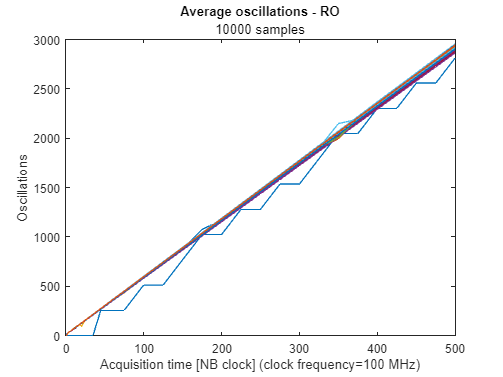

figure;
for i=1:length(limits)
    plot(limits, cells_averages(i,:));
    hold on;
end
title("Average oscillations - RO");
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");

xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");

### Average cells oscillations (zoomed)

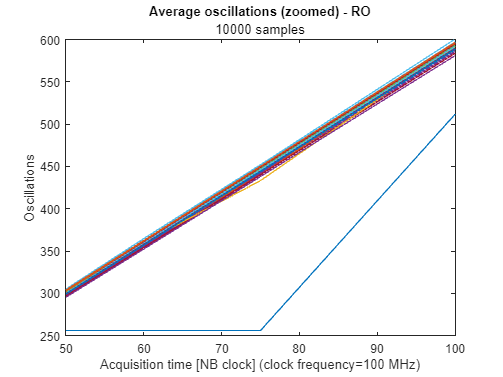

figure;
for i=1:length(limits)
    plot(limits, cells_averages(i,:));
    hold on;
end
title("Average oscillations (zoomed) - RO");
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");

xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
xlim([50 100]);
ylim([250 600]);

## TERO cell (4-LUT)

prefix="tero_4_count_limit";
cells_averages = zeros(n_cells, length(limits));

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    for j=1:n_cells
        cells_averages(j,i) = mean(data(start_index:end_index,j));
    end
end

### Average cells oscillations

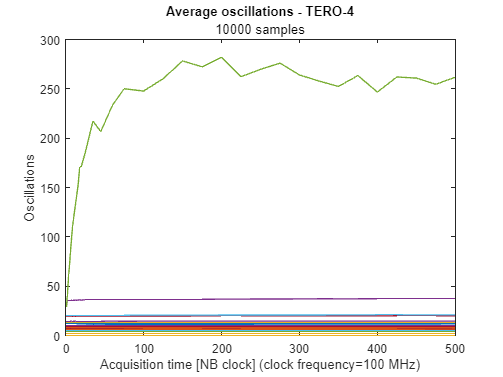

figure;
for i=1:length(limits)
    plot(limits, cells_averages(i,:));
    hold on;
end
title("Average oscillations - TERO-4");
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");

### Average cells oscillations (zoomed)

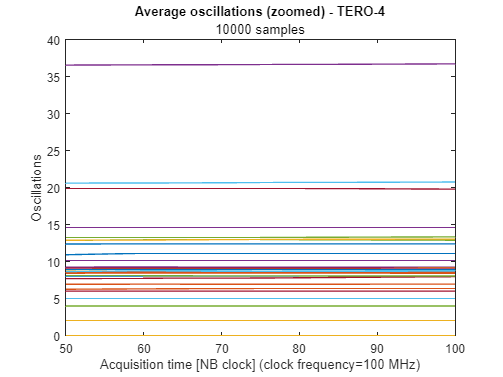

figure;
for i=1:length(limits)
    plot(limits, cells_averages(i,:));
    hold on;
end
title("Average oscillations (zoomed) - TERO-4");
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
xlim([50 100]);
ylim([0 40]);

## TERO cell (8-LUT)

prefix="tero_8_count_limit";
cells_averages = zeros(n_cells, length(limits));

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    for j=1:n_cells
        cells_averages(j,i) = mean(data(start_index:end_index,j));
    end
end

### Average cells oscillations

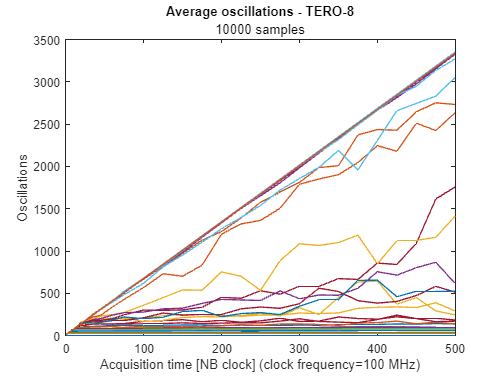

figure;
for i=1:length(limits)
    plot(limits, cells_averages(i,:));
    hold on;
end
title("Average oscillations - TERO-8");
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");

xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");

### Average cells oscillations (zoomed)

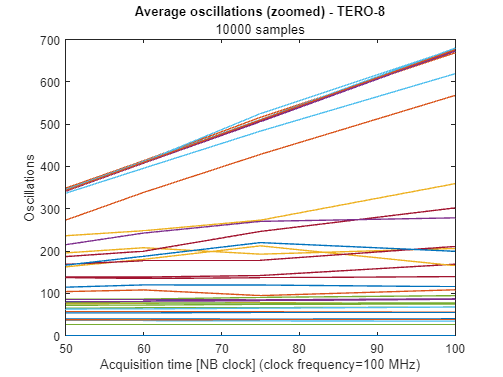

figure;
for i=1:length(limits)
    plot(limits, cells_averages(i,:));
    hold on;
end
title("Average oscillations (zoomed) - TERO-8");
subtitle(string(n_sample)+" samples");
ylabel("Oscillations");

xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");

xlim([50 100]);
ylim([0 700]);